clear; clc; close all;

img = imread('cat.png');
img = imresize(img, [128 128]);
img = rgb2gray(img);

img_bin = de2bi(img(:), 8, 'left-msb');
data_bits = reshape(img_bin.', [], 1);

key = randi([0 1], length(data_bits), 1);
encrypted_bits = xor(data_bits, key);

pad_len = mod(4 - mod(length(encrypted_bits), 4), 4);
padded_bits = [encrypted_bits; zeros(pad_len, 1)];
reshaped_bits = reshape(padded_bits, 4, []).';
encoded = encode(reshaped_bits, 7, 4, 'hamming/binary');
encoded_bits = reshape(encoded.', [], 1);

symb_data = reshape(encoded_bits, [], 2);
symb_dec = bi2de(symb_data, 'left-msb');
mod_signal = pskmod(symb_dec, 4, pi/4);

rx_signal = awgn(mod_signal, 25, 'measured');

rx_symb = pskdemod(rx_signal, 4, pi/4);
rx_bits = de2bi(rx_symb, 2, 'left-msb');
rx_out = reshape(rx_bits.', [], 1);

rx_out = rx_out(1:floor(length(rx_out)/7)*7);
rx_matrix = reshape(rx_out, 7, []).';
decoded = decode(rx_matrix, 7, 4, 'hamming/binary');
decoded_bits = reshape(decoded.', [], 1);
decoded_bits = decoded_bits(1:length(encrypted_bits));

decrypted_bits = xor(decoded_bits, key);

bin_matrix = reshape(decrypted_bits, 8, []).';
pixel_values = bi2de(bin_matrix, 'left-msb');
rec_img = reshape(pixel_values, size(img));

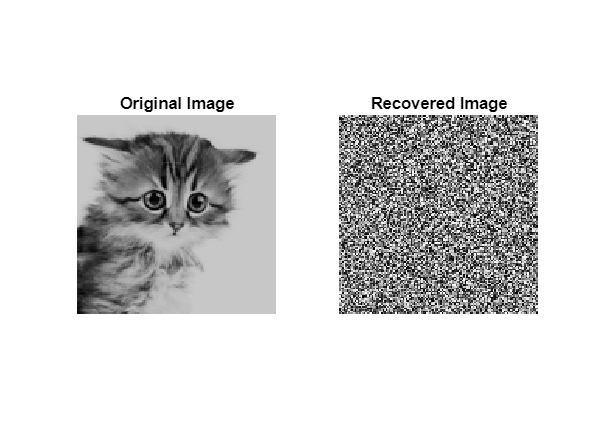

subplot(1,2,1); imshow(img); title('Original Image');
subplot(1,2,2); imshow(uint8(rec_img)); title('Recovered Image');


mse = mean((double(img(:)) - double(rec_img(:))).^2);
psnr_val = 10*log10(255^2 / mse);
fprintf('\nPSNR: %.2f dB\n', psnr_val);


PSNR: 8.55 dB
